clc % clear command window
clear % clear MATLAB workspace

**Set up robot control system**

% create arduino ref-objects
    [robotArduino, rawRangeIn, blinkLED]= SETUPARDUINO('COM8');
    
% Turn on board LED on and off to signal program has started
    Blink(robotArduino,blinkLED,3);
    disp('Warning! Position Servo Active! ');

Warning! Position Servo Active! 


% Configuration test loop to collect n points
    nTests = input(['Enter number of range test position, '...
        'followed by enter: ']);
  clc
    
% Create a variable to hold experimental position data
    positionData = zeros(nTests,2);
    
r = rateControl(0.25);
reset(r);

**Run Robot Control Loop**

controlFlag = 1;                    % create a loop control
while (controlFlag < nTests+1)      % loop till ntests data captured
    
    for i = 1:10
        rangeData(i) = SENSE(robotArduino, rawRangeIn);
    end
    rangeData = mean(rangeData)
    
    THINK(); % compute what the robot should do next    
    ACT(); % command robot actuators
    
    % store experimental commanded versus actual data
    positionData(controlFlag,1) = input('Enter actual distance(cm): ');
    gtest = input('move Sonar to new range, type G and then hit Enter','s')
    positionData(controlFlag,2) = rangeData;
    Blink(robotArduino, blinkLED, 1);
    waitfor(r);                     % wait for code cycle to complete
    controlFlag = controlFlag + 1;  %increment loop
end

**Sensor testing (print voltage repeatedly)**

entries = 30;
% pause_time = 0.1;
t = linspace(0,entries*pause_time,entries);
distance_arr = [];
for i = 1:entries    
    for j = 1:20
        voltage(j) = readVoltage(robotArduino, rawRangeIn);
    end
        avg_voltage = mean(voltage);

    distance_arr(i) = voltage_to_distance(avg_voltage);
    pause(pause_time);
end

t

t =          0    0.1034    0.2069    0.3103    0.4138    0.5172    0.6207    0.7241    0.8276    0.9310    1.0345    1.1379    1.2414    1.3448    1.4483    1.5517    1.6552    1.7586    1.8621    1.9655    2.0690    2.1724    2.2759    2.3793    2.4828    2.5862    2.6897    2.7931    2.8966    3.0000


distance_arr

distance_arr =   135.0051  140.5170  128.8808  130.3098  129.9526  146.1819  135.4645  132.6065  121.7359  118.2654  137.3528  115.0502   71.6698   62.0241   80.3459  137.1997  102.6485  113.9274  127.8601  130.0547  136.6383  140.4149  132.1982  121.3786   79.5804   51.1535   59.7785  134.6989  132.5044  131.5347


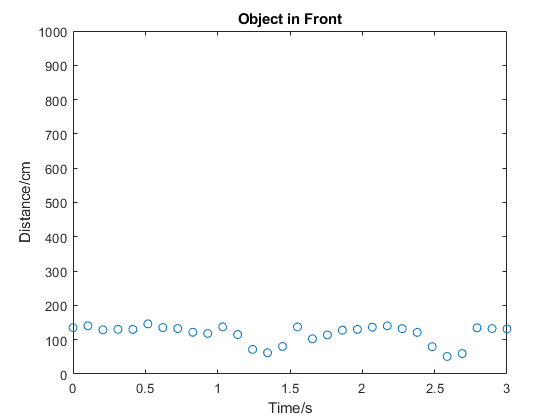

plot(t, distance_arr, 'o')
ylim([0, 1000])
title("Object in Front")
xlabel('Time/s')
ylabel('Distance/cm')

**Mission data processing**

For many robot appliaction, you will need to post-process the data collected after the mission. Here we will plot the desied versus actual motor positions.

% Plot and store commanded position data vs. actual position
% plot(positionData(:,1), positionData(:,2), '-*')
% ylabel('Measured Voltage')
% xlabel('Actual Position')
% cftool(positionData(:,1), positionData(:,2))
% grid

Linear Fit

fig = openfig('positionDataFinalWhite.fig');
axObjs = fig.Children;
dataObjs = axObjs.Children;
x = dataObjs(1).XData;
x = x+35

x =     39    41    43    45    47    49    51    53    55    57


y = dataObjs(1).YData;
plot(x,y)
c = polyfit(x, y, 1)

c =     0.0048   -0.0211


disp(['Equation is y = ' num2str(c(1)) '*x + ' num2str(c(2))])

Equation is y = 0.0047884*x + -0.021092


new_y = voltage_to_distance(y)

new_y =    39.9256   40.0277   43.0899   44.9271   46.5603   49.2141   51.2556   53.0929   54.6239   57.2778


plot(x,new_y,'o')

**Clean shut down**

finally, with most embedded robot controllers, it's good practice to put all actuators into a safe postion and then release all control objects and shut down all communication paths. This keeps systems from jamming when you want to run again.

% Stop program and clean up the connection to Arduino when no longer needed
clc
disp('Arduino program has ended');

clear robotArduino
beep           % play system sound to let user know program is ended

**Robot Functions**

function [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot
% controller. It requires which COM Port your Arduino is attached to as its
% input and returns an Arduino object called robotArduino. 

% Creates a global arduino object so that it can be used in functions 
% a = arduino('setToYourComNumber','Uno',Libraries','Servo');
    robotArduino = arduino(COMPORT, 'Uno','Libraries','Servo');

% configure pin 13 as a digital-out LED
    blinkLED = 'D13';
    configurePin(robotArduino,blinkLED,'DigitalOutput');

% configure A0 pin as an analog input
    rawRangeIn = 'A2';
    configurePin(robotArduino, rawRangeIn, 'AnalogInput')
end

function [] = Blink(a,LED,n)
% Blink toggles Arduino a LED on and off to indicate program running input
% n is number of blinks
% no output is returned
    for bIndex = 1:n
        writeDigitalPin(a,LED,0);
        pause(0.2);
        writeDigitalPin(a,LED,1);
        pause(0.2);
    end
end

**Sense Function** (store all Sense related Local functions)

function rangeData = SENSE(robotArduino, rawRangeIn)
disp('Sense');
rangeData = readVoltage(robotArduino, rawRangeIn);
end

**Think Function **(store all Think related Local functions)

function THINK()
    % null function, not much thinking to do here
end

function distance = voltage_to_distance(voltage)
    distance = (voltage + 0.021092)/ 0.0047884;
%     Equation is y = 0.0047884*x + 0.1465
% Equation is y = 0.0047884*x + -0.021092
end

**Act Function **(store all Act related Local functions)

function ACT()
% null function    
end